# Setup 

addpath('functions'); % adiciona o caminho das nossas funcoes
format long

## Estudo dos diferentes criterios 

A = vander([1, 3, 5, 7, 9]); % Gera a matriz de Vandermonde pedida

epsilons = [0.1, 1e-3, 1e-6, 1e-9, 1e-12, 1e-15]; % O vetor dos \epsilons
n_max = 2000; % numero maximo de iteracoes que vamos utilizar

valores_iter_1 = zeros(length(epsilons), 1); % formula (12)
valores_iter_2 = zeros(length(epsilons), 1); % formula (13)
valores_iter_test = zeros(length(epsilons), 1); % valores para a \|X_{k+1}-X_K\|
valores_iter_test2 = zeros(length(epsilons), 1); % valores para a do \|R_k\|

for k = 1:length(epsilons)
    epsilon_atual = epsilons(k);

    [~, iter_1, ~] = Newton_Schulz_erro_1_autoX0(A,n_max,epsilon_atual); % formula (12)
    [~, iter_2, ~] = Newton_Schulz_erro_2_autoX0(A,n_max,epsilon_atual); % formula (13)
    [~, iter_3, ~] = Newton_Schulz_test(A,n_max,epsilon_atual); % valores para a \|X_{k+1}-X_K\|
    [~, iter_4, ~] = Newton_Schulz_test2(A,n_max,epsilon_atual); % valores para a do \|R_k\|

    valores_iter_1(k) = iter_1;
    valores_iter_2(k) = iter_2;
    valores_iter_test(k) = iter_3;
    valores_iter_test2(k) = iter_4;
end

## Fazer a tabela dos diferentes criterios 

cabecalho = [{'Critério \ Epsilon'}, num2cell(epsilons)];

F1_texto = 'Formula (12)';
F2_texto = 'Formula (13)';
F3_texto = '\|X_{k+1}-X_k\|';
F4_texto = '\|R_k\|';

linha_F1 = [{F1_texto}, num2cell(valores_iter_1(:)')];

linha_F2 = [{F2_texto}, num2cell(valores_iter_2(:)')];

linha_F3 = [{F3_texto}, num2cell(valores_iter_test(:)')];

linha_F4 = [{F4_texto}, num2cell(valores_iter_test2(:)')];

TabelaFinal = [cabecalho; linha_F1; linha_F2; linha_F3; linha_F4];

clc;
disp(TabelaFinal);

    {'Critério \ Epsilon'}    {[0.100000000000000]}    {[1.000000000000000e-03]}    {[1.000000000000000e-06]}    {[1.000000000000000e-09]}    {[1.000000000000000e-12]}    {[1.000000000000000e-15]}
    {'Formula (12)'      }    {[               35]}    {[                   36]}    {[                   37]}    {[                   37]}    {[                   37]}    {[                 2000]}
    {'Formula (13)'      }    {[               35]}    {[                   36]}    {[                   37]}    {[                   37]}    {[                 1125]}    {[                 2000]}
    {'\|X_{k+1}-X_k\|'   }    {[                0]}    {[                    0]}    {[                   37]}    {[                   37]}    {[                   37]}    {[                 2000]}
    {'\|R_k\|'           }    {[               34]}    {[                   35]}    {[                   36]}    {[                   37]}    {[                   42]}    {[                 2000]}



## Estudo das restantes matrizes 

tamanhos = [5, 7, 10, 15, 20, 25]; % tamanhos que vamos estudar
matrizes_An = cell(length(tamanhos), 1); % lista das matrizes que vamos estudar

## Codigo para produzir as matrizes A_n 

for i = 1:length(tamanhos)
    n = tamanhos(i);

    d_principal = 10 * ones(n, 1);
    d_principal(1) = 9;
    d_secundaria = 3 * ones(n-1, 1);

    An = diag(d_principal) + diag(d_secundaria, 1) + diag(d_secundaria, -1);

    matrizes_An{i} = An;
end

## Codigo para produzir as matrizes de Hilbert 

for i = 1:length(tamanhos)
    n = tamanhos(i);
    An = hilb(n);
    matrizes_An{i} = An;
end

## Codigo para produzir as matrizes de Lehmer 

for i = 1:length(tamanhos)
    n = tamanhos(i);
    An = gallery('lehmer', n);
    matrizes_An{i} = An;
end

## Resto do codigo 

Atencao: Este código vai produzir os dados para a tabela consuante qual seccao de matrizes foi a ultima a ser corrida

epsilons = [0.1, 1e-3, 1e-6, 1e-9, 1e-12, 1e-15]; % Vetor do \epsilons
n_max = 2000; % numero maximo de itereções que vamos usar caso uma cécula de 2000 cosideramos que o metodo n convergiu

valores_iter_5 =  zeros(length(epsilons), 1);
valores_iter_7 =  zeros(length(epsilons), 1);
valores_iter_10 =  zeros(length(epsilons), 1);
valores_iter_15 =  zeros(length(epsilons), 1);
valores_iter_20 =  zeros(length(epsilons), 1);
valores_iter_25 =  zeros(length(epsilons), 1);

for k = 1:length(epsilons)
    epsilon_atual = epsilons(k);

    [~, iter_5, ~] = Newton_Schulz_erro_1_autoX0(matrizes_An{1},n_max,epsilon_atual);
    [~, iter_7, ~] = Newton_Schulz_erro_1_autoX0(matrizes_An{2},n_max,epsilon_atual);
    [~, iter_10, ~] = Newton_Schulz_erro_1_autoX0(matrizes_An{3},n_max,epsilon_atual);
    [~, iter_15, ~] = Newton_Schulz_erro_1_autoX0(matrizes_An{4},n_max,epsilon_atual);
    [~, iter_20, ~] = Newton_Schulz_erro_1_autoX0(matrizes_An{5},n_max,epsilon_atual);
    [~, iter_25, ~] = Newton_Schulz_erro_1_autoX0(matrizes_An{6},n_max,epsilon_atual);

    valores_iter_1(k) = iter_5;
    valores_iter_2(k) = iter_7;
    valores_iter_3(k) = iter_10;
    valores_iter_4(k) = iter_15;
    valores_iter_5(k) = iter_20;
    valores_iter_6(k) = iter_25;
end

## Tabela do numero de iteracoes para um dado tamanho n e tolerancia \epsilon 

cabecalho = [{'Iteração por tamnho'}, num2cell(epsilons)];

F1_texto = 'n = 5';
F2_texto = 'n = 7';
F3_texto = 'n = 10';
F4_texto = 'n = 15';
F5_texto = 'n = 20';
F6_texto = 'n = 25';

linha_F1 = [{F1_texto}, num2cell(valores_iter_1(:)')];
linha_F2 = [{F2_texto}, num2cell(valores_iter_2(:)')];
linha_F3 = [{F3_texto}, num2cell(valores_iter_3(:)')];
linha_F4 = [{F4_texto}, num2cell(valores_iter_4(:)')];
linha_F5 = [{F5_texto}, num2cell(valores_iter_5(:)')];
linha_F6 = [{F6_texto}, num2cell(valores_iter_6(:)')];

TabelaFinal = [cabecalho; linha_F1; linha_F2; linha_F3; linha_F4;linha_F5;linha_F6];

clc;
disp(TabelaFinal);

    {'Iteração por tamnho'}    {[0.100000000000000]}    {[1.000000000000000e-03]}    {[1.000000000000000e-06]}    {[1.000000000000000e-09]}    {[1.000000000000000e-12]}    {[1.000000000000000e-15]}
    {'n = 5'              }    {[                5]}    {[                    8]}    {[                    9]}    {[                    9]}    {[                   10]}    {[                   10]}
    {'n = 7'              }    {[                6]}    {[                    8]}    {[                    9]}    {[                   10]}    {[                   11]}    {[                   11]}
    {'n = 10'             }    {[                7]}    {[                    9]}    {[                   10]}    {[                   11]}    {[                   11]}    {[                   12]}
    {'n = 15'             }    {[                8]}    {[                   10]}    {[                   11]}    {[                   11]}    {[                   12]}    {[                   12]}
    {'n = 

## Código para gerar mas matrizes inversas 

n = 5; % tamanho da matriz
epsilon = 1e-12; % precisao
n_max = 10000;
matrizes_An = cell(3, 1);

d_principal = 10 * ones(n, 1); % código auxiliar para gerar a matriz A_n
d_principal(1) = 9;
d_secundaria = 3 * ones(n-1, 1);

A = diag(d_principal) + diag(d_secundaria, 1) + diag(d_secundaria, -1);
B = hilb(n);
C = gallery("lehmer",n);

matrizes_An{1} = A;
matrizes_An{2} = B;
matrizes_An{3} = C;

for k = 1:length(matrizes_An)
    A_n = matrizes_An{k};
    [X_out ,~ ,~ ] = Newton_Schulz_erro_1_autoX0(A_n,n_max,epsilon);
    A_inv = inv(A);
    disp(A_inv)
    disp(X_out)
    N = norm(X_out-A_inv,'fro'); % diferencia entre  o metodo e a funcao inv
    fprintf("%d\n",N)
end

   0.124997883114024  -0.041660316008739   0.013869836915104  -0.004572473708276   0.001371742112483
  -0.041660316008739   0.124980948026216  -0.041609510745313   0.013717421124829  -0.004115226337449
   0.013869836915104  -0.041609510745313   0.124828532235940  -0.041152263374486   0.012345679012346
  -0.004572473708276   0.013717421124829  -0.041152263374486   0.123456790123457  -0.037037037037037
   0.001371742112483  -0.004115226337449   0.012345679012346  -0.037037037037037   0.111111111111111



   0.124997883114024  -0.041660316008739   0.013869836915104  -0.004572473708276   0.001371742112483
  -0.041660316008739   0.124980948026216  -0.041609510745313   0.013717421124829  -0.004115226337449
   0.013869836915104  -0.041609510745313   0.124828532235940  -0.041152263374486   0.012345679012346
  -0.004572473708276   0.013717421124829  -0.041152263374486   0.123456790123457  -0.037037037037037
   0.001371742112483  -0.004115226337449   0.012345679012346  -0.037037037037037   0.111111111111111



2.908654e-17


   0.124997883114024  -0.041660316008739   0.013869836915104  -0.004572473708276   0.001371742112483
  -0.041660316008739   0.124980948026216  -0.041609510745313   0.013717421124829  -0.004115226337449
   0.013869836915104  -0.041609510745313   0.124828532235940  -0.041152263374486   0.012345679012346
  -0.004572473708276   0.013717421124829  -0.041152263374486   0.123456790123457  -0.037037037037037
   0.001371742112483  -0.004115226337449   0.012345679012346  -0.037037037037037   0.111111111111111



   1.0e+05 *

   0.000250000000000  -0.002999999999997   0.010499999999990  -0.013999999999987   0.006299999999994
  -0.002999999999993   0.047999999999877  -0.188999999999484   0.268799999999233  -0.125999999999629
   0.010499999999942  -0.188999999998955   0.793799999995600  -1.175999999993470   0.566999999996847
  -0.014000000000014   0.268800000000317  -1.176000000001504   1.792000000002417  -0.882000000001235
   0.006299999999988  -0.125999999999780   0.566999999999049  -0.881999999998564   0.440999999999297



3.041602e+05


   0.124997883114024  -0.041660316008739   0.013869836915104  -0.004572473708276   0.001371742112483
  -0.041660316008739   0.124980948026216  -0.041609510745313   0.013717421124829  -0.004115226337449
   0.013869836915104  -0.041609510745313   0.124828532235940  -0.041152263374486   0.012345679012346
  -0.004572473708276   0.013717421124829  -0.041152263374486   0.123456790123457  -0.037037037037037
   0.001371742112483  -0.004115226337449   0.012345679012346  -0.037037037037037   0.111111111111111



   1.333333333333333  -0.666666666666667  -0.000000000000000   0.000000000000000   0.000000000000000
  -0.666666666666667   2.133333333333333  -1.200000000000000  -0.000000000000000  -0.000000000000000
  -0.000000000000000  -1.200000000000000   3.085714285714286  -1.714285714285714   0.000000000000000
  -0.000000000000000   0.000000000000000  -1.714285714285715   4.063492063492064  -2.222222222222222
  -0.000000000000000  -0.000000000000000   0.000000000000001  -2.222222222222224   2.777777777777778



7.450527e+00


## Ordem de convergencia computacional 

n = 48; % numero maximo de iteracoes
I = eye(n);
I2 = eye(5); % matriz identidade para a matriz de Vandermonde

d_principal = 10 * ones(n, 1);
d_principal(1) = 9;
d_secundaria = 3 * ones(n-1, 1);

A = diag(d_principal) + diag(d_secundaria, 1) + diag(d_secundaria, -1);
B = hilb(n);
C = gallery('lehmer',n);
D = vander([1, 3, 5, 7, 9]);

% Setup inicial

X_0_A = A' / (norm(A, 'fro')^2);
X_0_B = B' / (norm(B, 'fro')^2);
X_0_C = C' / (norm(C, 'fro')^2);
X_0_D = D' / (norm(D, 'fro')^2);

R_0_A = I - A*X_0_A;
R_1_A = R_0_A*R_0_A;
R_2_A = R_1_A*R_1_A;
R_0_B = I - B*X_0_B;
R_1_B = R_0_B*R_0_B;
R_2_B = R_1_B*R_1_B;
R_0_C = I - C*X_0_C;
R_1_C = R_0_C*R_0_C;
R_2_C = R_1_C*R_1_C;
R_0_D = I2 - D*X_0_D;
R_1_D = R_0_D*R_0_D;
R_2_D = R_1_D*R_1_D;

valores_p_A = zeros(n,1); % lista onde vamos guardar os valores de p
valores_p_B = zeros(n,1);
valores_p_C = zeros(n,1);
valores_p_D = zeros(n,1);

for k = 1:n
    p_A = (log(norm(R_2_A,'fro'))-log(norm(R_1_A,'fro')))/(log(norm(R_1_A,'fro'))-log(norm(R_0_A,'fro')));
    p_B = (log(norm(R_2_B,'fro'))-log(norm(R_1_B,'fro')))/(log(norm(R_1_B,'fro'))-log(norm(R_0_B,'fro')));
    p_C = (log(norm(R_2_C,'fro'))-log(norm(R_1_C,'fro')))/(log(norm(R_1_C,'fro'))-log(norm(R_0_C,'fro')));
    p_D = (log(norm(R_2_D,'fro'))-log(norm(R_1_D,'fro')))/(log(norm(R_1_D,'fro'))-log(norm(R_0_D,'fro')));

    valores_p_A(k) = p_A; % adiciona os novos valores de p á lista
    valores_p_B(k) = p_B;
    valores_p_C(k) = p_C;
    valores_p_D(k) = p_D;

    R_0_A = R_1_A;  R_1_A = R_2_A;  R_2_A = R_1_A*R_1_A; % faz a p´roxima iteração
    R_0_B = R_1_B;  R_1_B = R_2_B;  R_2_B = R_1_B*R_1_B;
    R_0_C = R_1_C;  R_1_C = R_2_C;  R_2_C = R_1_C*R_1_C;
    R_0_D = R_1_D;  R_1_D = R_2_D;  R_2_D = R_1_D*R_1_D;
end

## Grafico 

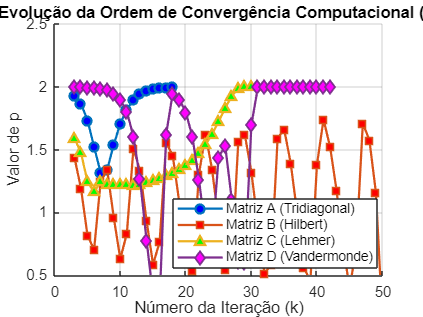

% ESTE GRÁFICO GERA O GRÁFICO QUE SE ENCONTRA NO RELATÓRIO

figure;
hold on;

plot(3:n+2, valores_p_A, '-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b', 'DisplayName', 'Matriz A (Tridiagonal)');
plot(3:n+2, valores_p_B, '-s', 'LineWidth', 1.5, 'MarkerFaceColor', 'r', 'DisplayName', 'Matriz B (Hilbert)');
plot(3:n+2, valores_p_C, '-^', 'LineWidth', 1.5, 'MarkerFaceColor', 'g', 'DisplayName', 'Matriz C (Lehmer)');
plot(3:n+2, valores_p_D, '-d', 'LineWidth', 1.5, 'MarkerFaceColor', 'm', 'DisplayName', 'Matriz D (Vandermonde)');

hold off;

grid on;
title('Evolução da Ordem de Convergência Computacional (p)');
xlabel('Número da Iteração (k)');
legend('show', 'Location', 'best');
ylabel('Valor de p');
ylim([0.5 2.5]);